# Attacking Learn++.NSE

In this notebook we will be attacking Learn++.NSE. 

The types of attacks are

- Create a model to predict the future locations of cluster centroids using SINDy. From the predicted clusters at timestep $t$, use AdvLearn to generate attack points. Insert those attack points into the training data of $t$.

- Create a model to predict the future locations of cluster centroids using SINDy. From the predicted clusters at timestep $t$, randomly select points, flip their labels. Insert those attack points into the training data of $t$.

- Based on the actual clusters from timestep $t_{\text{past}}$ generate attack points using AdvLearn. Insert those attack points into the training data of current time step. 

For all attacks we are assuming we do not know the labels of the incoming clusters until they have been classified by Learn++.NSE. So to attack a particular timestep, either predict where the clusters will be and generate attack points accordingly. Alternatively, we could generate attacks based on the clusters of previous timesteps. 

pathsForCode();
dataset = "X2CDT_FastMoving";
kernel = "Linear";
lambda = 8e-3;
polyOrder = 1;
useSine = 0;
sineMultiplier = 10;
useExp = 0;
expMultiplier = 10;
maxSteps = 250;
stepSize = 5;
degree = 3;
coef0 = 1;
c = 1; % Class to attack
numAtkPts = 40;

[nseData_Baseline,nseResults_Baseline,...
	   ~,~,~,~] = ...
	   LearnPlusPLusNSE_Baseline(dataset,... % General setting
                                     kernel); 

[classInfo_AdvLearnSINDy,...
nseData_AdvLearnSINDy,nseResults_AdvLearnSINDy,...
numClasses,numDims,numObs,numTimesSteps,...
SINDyData_AdvLearnSINDy,SINDyResults_AdvLearnSINDy,...
atkData_AdvLearnSINDy,genDistr_AdvLearnSINDy] = ...
...
attackingLearnPlusPlus_chrisAttack_SINDy(dataset,... % General setting
                                        kernel,... % Learn++.NSE & AttackSVM setting
                                        lambda,polyOrder,... % SINDy Setting
                                        useSine,sineMultiplier,... % SINDy Setting
                                        useExp,expMultiplier,... % SINDy Setting
                                        maxSteps,stepSize,... % AttackSVM setting
                                        degree,coef0,... % AttackSVM setting
                                        numAtkPts,c); % AttackSVM setting
                                         

timeStepsInPastToAttack = 4;
[nseData_AdvLearn,nseResults_AdvLearn,...
~,~,~,~,...
atkData_AdvLearn] = attackingLearnPlusPlus_AdvLearn(dataset,... % General setting
                                           kernel,... % Learn++.NSE & AttackSVM setting
    		                           maxSteps,stepSize,... % AttackSVM setting
                		           degree,coef0,... % AttackSVM setting
                		           numAtkPts,... % AttackSVM setting
                                           timeStepsInPastToAttack,c); % AttackSVM setting

## Results

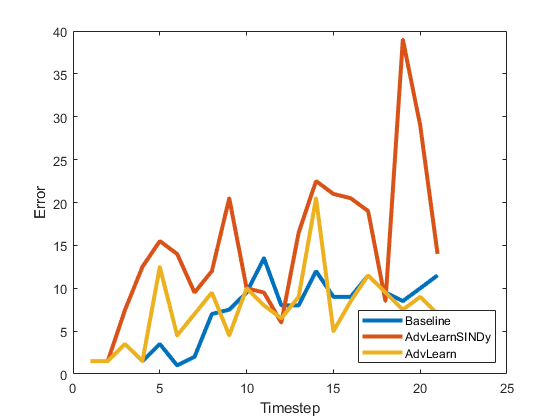

AdvLearnError = [nseResults_AdvLearn(1:21).errs_nse];
AdvLearnSINDyError = [nseResults_AdvLearnSINDy(1:21).errs_nse];
BaselineError = [nseResults_Baseline(1:21).errs_nse];

Error(1,:) = BaselineError;
Error(2,:) = AdvLearnSINDyError;
Error(3,:) = AdvLearnError;
figure
plot((1:21)',Error'*100,'LineWidth',3)
xlabel('Timestep')
ylabel('Error')
legend('Baseline','AdvLearnSINDy','AdvLearn','Location','SouthEast')

### AdvLearn With SINDy 

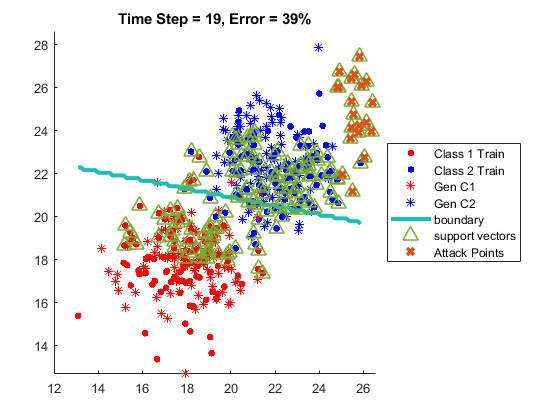

timeStep = 19;
svmNumber = 1;
svmMatch = true;
plotGenData = true;
plotPrevdata = true;
plotResultsAdvLearnSINDy(genDistr_AdvLearnSINDy,atkData_AdvLearnSINDy,nseResults_AdvLearnSINDy,timeStep,svmNumber,svmMatch,nseData_AdvLearnSINDy,plotGenData)

### AdvLearn

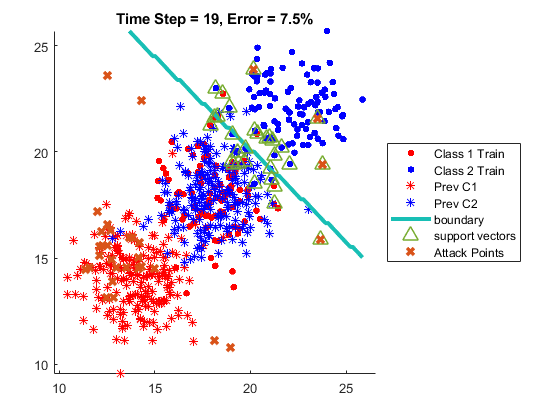

plotResultsAdvLearn(atkData_AdvLearn,nseResults_AdvLearn,timeStep,svmNumber,svmMatch,nseData_AdvLearn,timeStepsInPastToAttack,plotPrevdata)